# Plan Optimal Path Between Two States

Create a state space.

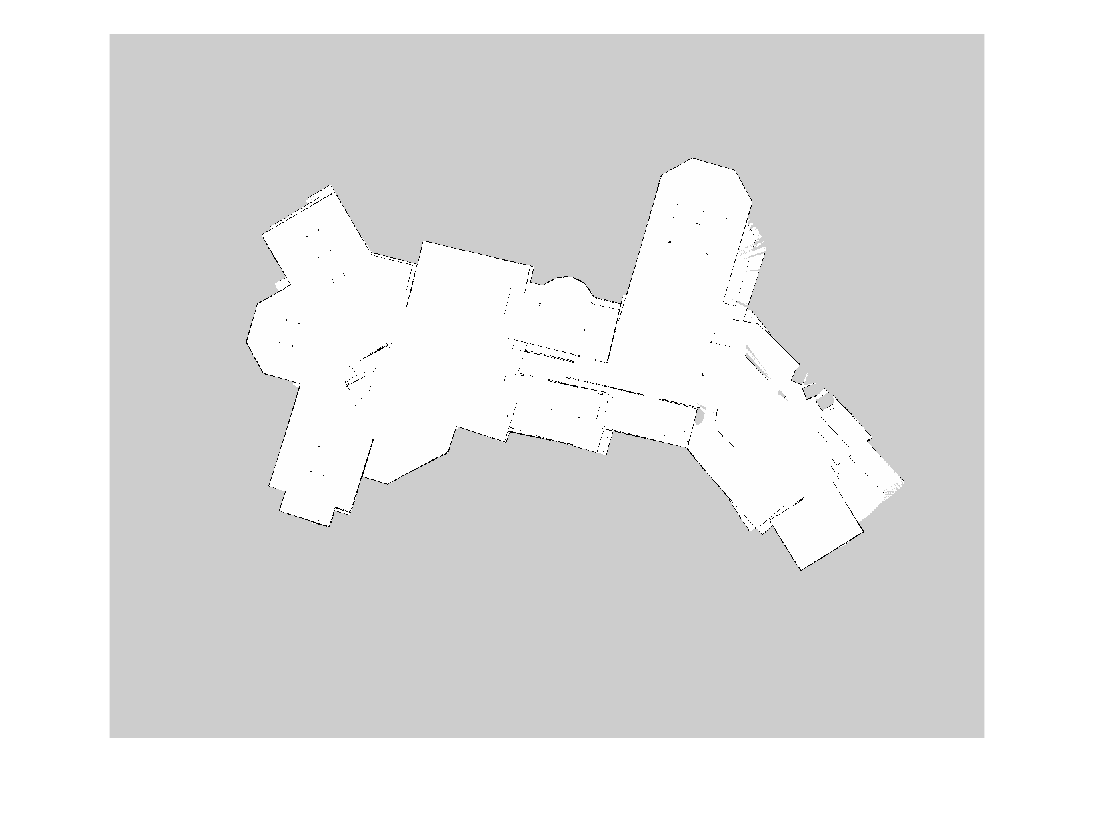

%RRTStarPlanner
imageCropped=imread('C:\Users\Tejal/Downloads/Office.pgm');
imshow(imageCropped)

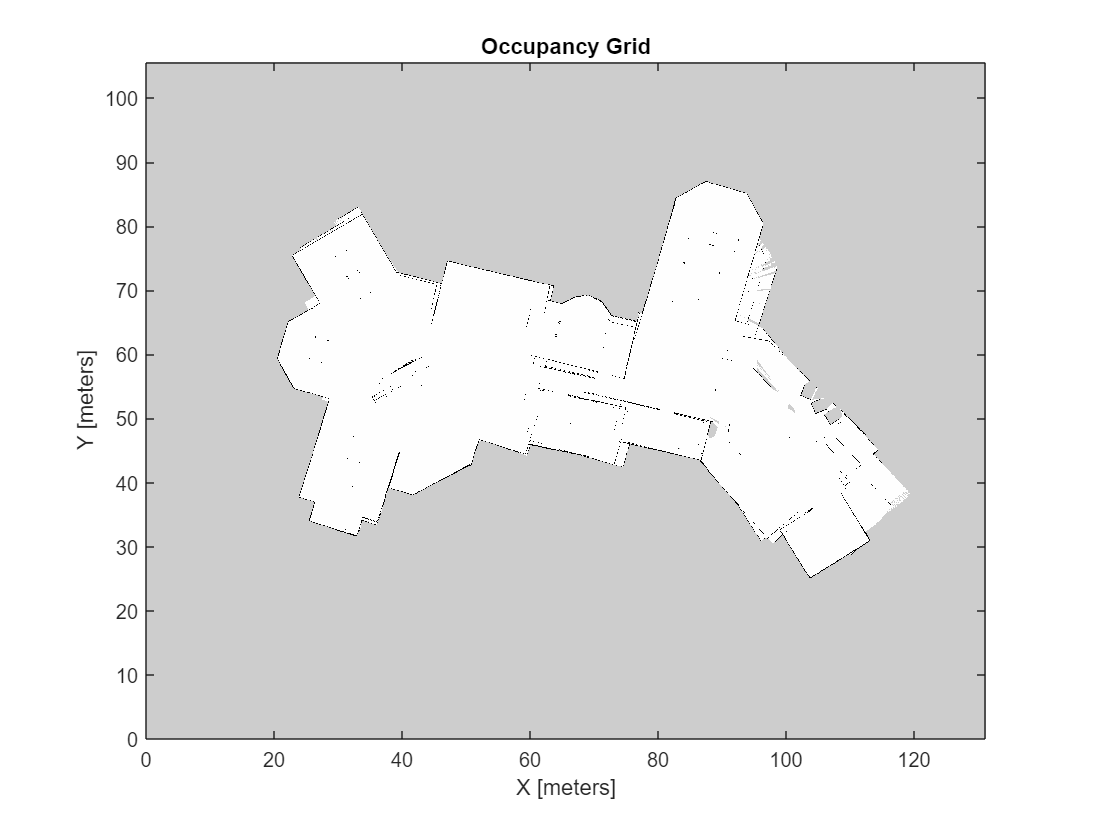

imageNorm=double(imageCropped)/255;
imageOcc=1-imageNorm;
map=occupancyMap(imageOcc,20);
load('mapredout.mat')
show(map)

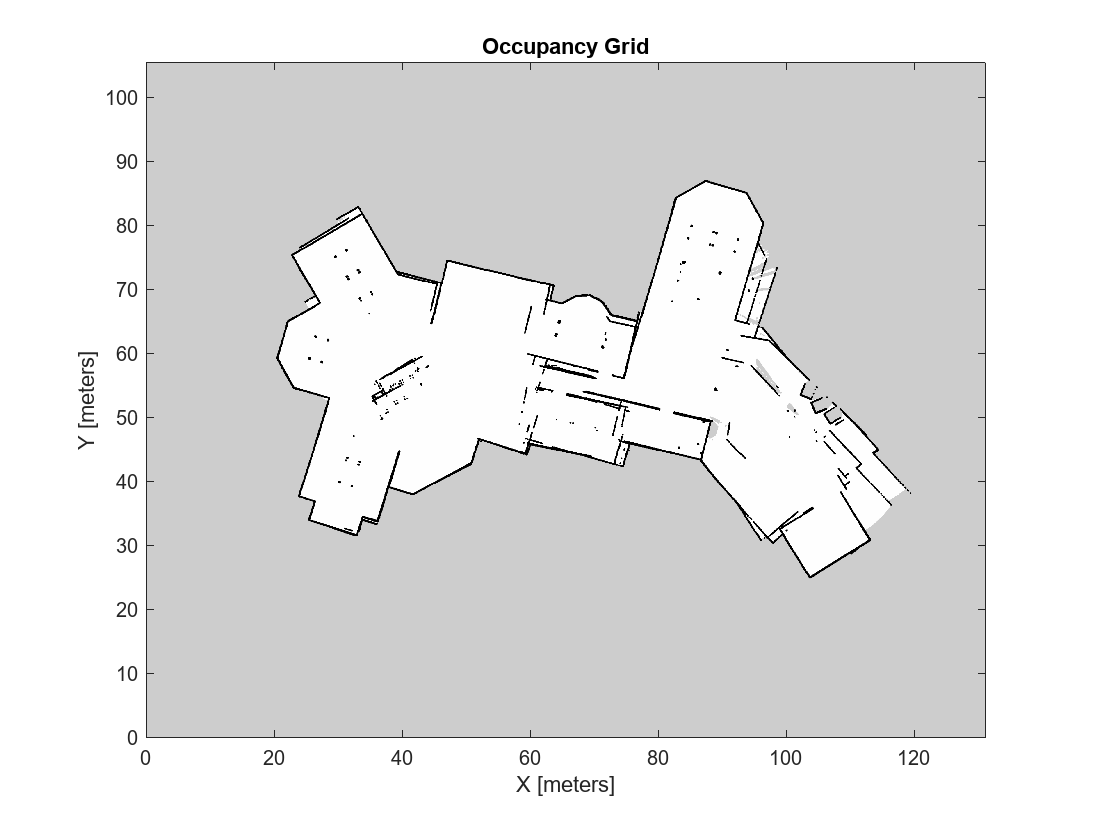

inflate(map,0.1)
show(map)

ss = stateSpaceSE2;

Create an `occupancyMap`-based state validator using the created state space.

sv = validatorOccupancyMap(ss);

Create an occupancy map from an example map and set map resolution as 10 cells/meter.

%map = occupancyMap(simpleMap,10);
sv.Map = map;

Set validation distance for the validator.

sv.ValidationDistance = 0.01;

Update state space bounds to be the same as map limits.

ss.StateBounds = [map.XWorldLimits; map.YWorldLimits; [-pi pi]];

Create RRT* path planner and allow further optimization after goal is reached. Reduce the maximum iterations and increase the maximum connection distance.

planner = plannerRRTStar(ss,sv, ...
          ContinueAfterGoalReached=true, ...
          MaxIterations=2500, ...
          MaxConnectionDistance=0.3);

Set the start and goal states.

start = [42,41,pi];
goal = [58,68,0];

Plan a path with default settings.

rng(100,'twister') % repeatable result
[pthObj,solnInfo] = plan(planner,start,goal);

Visualize the results.

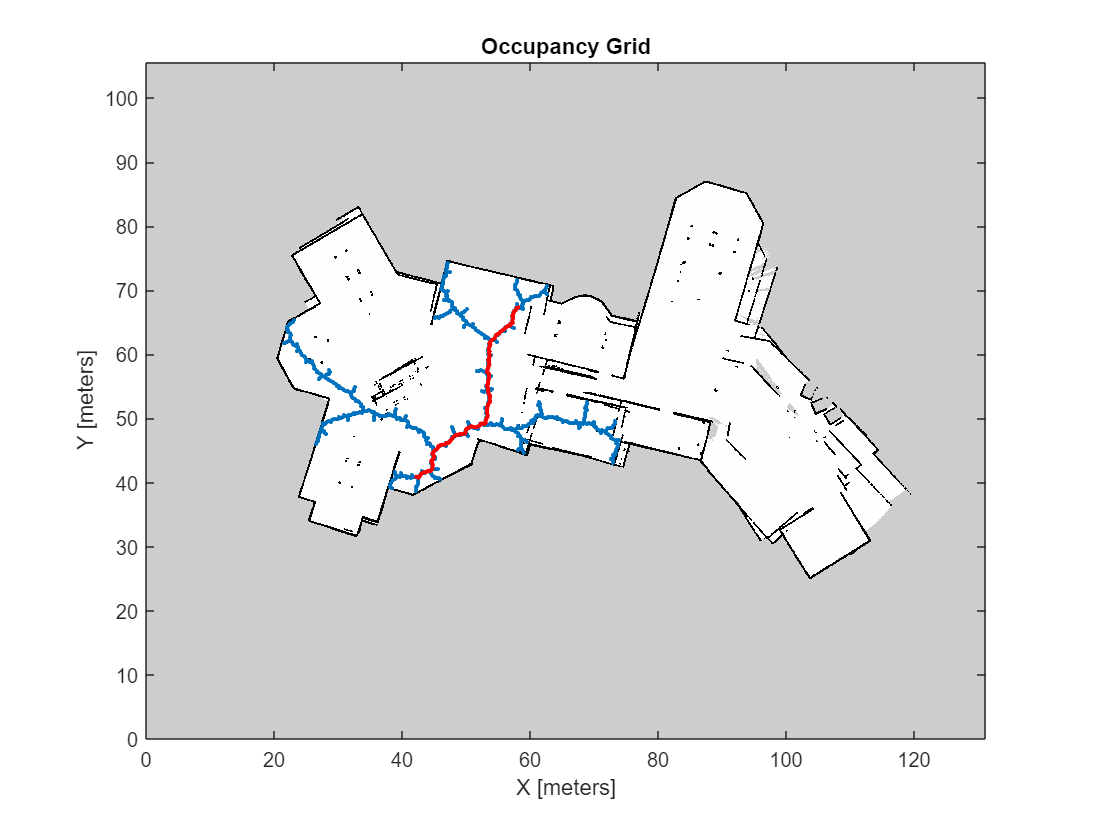

map.show
hold on
% Tree expansion
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-')
% Draw path
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2)

*Copyright 2019 The MathWorks, Inc.*